# **Study of FDTD Numerical Dispersion of a Pulse along a transmission-line**

We want to study the effect of the space and time discretization on the numerical dispersion of a TEM pulse propagating along a transmission line in the vacuum. 

This code is very similar to the previous one, but we perform here a loop over different values of the Courant ratio $\alpha$. For each vaue of $\alpha$, we perform an FDTD simulation and we compare the E field pulse at the same instant.

You should

- calculate the FDTD wavenumber (see slides about numerical dispersion in 1-D FDTD)

- define the sample points along the x axis for the E and the H fields (as in the previous code)

- define the sample instants for the E and H fields (as in the previous code)

- enforce the initial conditions (as in the previous code)

- writing the time update iteration: boundary condition at x=0, PEC boundary condition at x=XL, E update, H update (as in the previous code)

## Question A

Compare the pulses at the same instant with different Courant ratio (figure(1) in the code). What do you notice?

## **Question B**

Save a video for each value of Courant ratio (modify the loop over the "alpha" variable to force it only to a value instead of four). The video is saved with the figure(2).

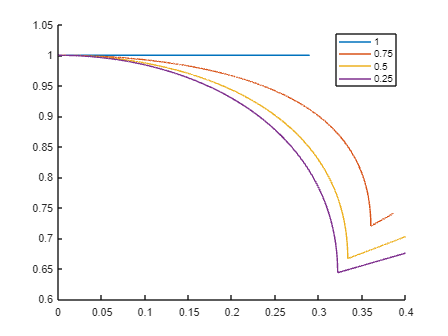

clearvars;
close all;

c0=3d8;               % Speed of light
mu0 = 4*pi*1.d-7;     % Vacuum magnetic permeability
eps0= 1.d-9/(36*pi);  % Vacuum dielectric permettivity

omega = 1.d9;         % Central angular frequency of the excitation
T = 2*pi/omega;       % Duration of the excitation
k0 = omega/c0;        % Free-space wavenumber at the central frequency of the excitation 

% Computational domain
TL = 6*T;             % Duration of the simulation (in seconds)
t0 = 0d-3;            % Initial time
XL = c0*TL;           % Endpoint of the transmission line
x0 = 0d-3;            % Left boundary along x (in meters)


% We have different values of the Courant limits. We perform a FDTD simulation for each of them.
alpha_choices = [1 0.75 0.5 0.25]; 
vp = zeros(size(alpha_choices));
for i=1:length(alpha_choices)

    alpha = alpha_choices(i);
    % Limit value for Delta_x, corresponding to sin(0.5*k Delta x)=1. If Delta_x>Delta_x_max, the FDTD does not see a propagating pulse.
    Delta_x_max = 2/alpha/k0*asin(alpha);   
    Delta_x = 0.4*Delta_x_max;
    if(i==1)
        Delta_x=0.025*Delta_x_max;
    end
    Delta_t = Delta_x*alpha/c0;
    
    % FDTD wavenumber as given in the FDTD 1-D dispersion equation (see slides)
    k_FDTD = 2/Delta_x*asin(sin(omega*Delta_t/2)/alpha);  % Complete here
    vp(i) = omega/k_FDTD;
    % Discretization
    NX = floor(XL/Delta_x);    % number of cells along the x direction
    NT = floor(TL/Delta_t);    % number of time intervals

    
    % Definition of the sampling instants for E and H
    t_E = t0 + Delta_t:Delta_t:TL;  % Complete here
    t_H = t0 + Delta_t/2 : Delta_t : TL - Delta_t/2;  % Complete here
    
    % Definition of the sampling x-points for E and H
    x_E= x0:Delta_x:XL;  % Complete here
    x_H= x0+Delta_x/2:Delta_x:XL-Delta_x/2;  % Complete here

        
    % Initial condition: E and H are equal to zero
    E(:) = zeros(size(x_E));   % Intialize E as a vector of size x_E
    H(:) = zeros(size(x_H));   % Intialize E as a vector of size x_H
    
    % FDTD update constants depending on epsilon, mu, Delta_x and Delta_t
    const_tx_eps = Delta_t/(eps0*Delta_x);     % Define the constant required in the E time updates
    const_tx_mu  = Delta_t/(mu0*Delta_x);      % Define the constant required in the H time updates
    A = double(t_E < T); 
    for time_instant=1:NT        % Time iteration (time update)
        
        % Boundary condition at x=0
        % Complete here
        E(1) = 1/2 *(1-cos(2*pi/T*t_E(time_instant))).*A(time_instant);

        % Boundary condition at x=XL
        % Complete here
        
        
        % E field update
        % Complete here
        E(2:end-1) = E(2:end-1) - const_tx_eps*(H(2:end)-H(1:end-1));
        
        % H field update
        % Complete here
        H(1:end) = H(1:end) - const_tx_mu*(E(2:end)-E(1:end-1));
        
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%        
        % Use this for the question A, comment it for the question B
%         % Plot of the E field (approximately) at the instant t=3.d8
%         if (t_E(time_instant) >= 3.d-8) && (t_E(time_instant) < 3.d-8+Delta_t)
%             figure(1)
%             plot(x_E,E)
%             axis([0 XL -0.5 1])
%             hold on
%         end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    
          % Use this for the question B, comment it for the question A
          % Plot of the E field to save a video of the pulse propagation 
%         figure(2)
%         plot(x_E,E)
%         axis([0 XL -1.5 1.5])
%         E_frames(time_instant) = getframe;
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% 
     end
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    
%       % Use this for the question B, comment it for the question A
%     filename=strcat(num2str(i),'_E_pulse_alpha=',num2str(alpha),'.avi')
%     writerObj = VideoWriter(filename);
%     open(writerObj);
%     writeVideo(writerObj, E_frames)
%     close(writerObj);
%     clear('E_frames','filename')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    


    % Clear simulation variables before solving a new FDTD with different discretization
    clear('E','H','x_E','x_H','t_E','t_H')

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Question supplémentaire : plot vp/c0 en fonction de alpha et
% Delta_x/(c*T)
Delta_x = c0*Delta_t./alpha_choices;
omega = 0:1.d6:9.d9;
figure(1)
xlim([0, 0.4])
hold on
for i = 1:length(alpha_choices) 
    k_FDTD = 2./Delta_x(i).*asin(sin(omega.*Delta_t/2)./alpha_choices(i));
    vp = omega./k_FDTD;
    X = Delta_x(i)./(c0*2*pi./omega);
    Y = vp/c0;
    plot(X, Y)
    legend(string(alpha_choices))
end% 

% figure(1)
% plot(X(1),Y(2))



% figure()
% plot(X(1), Y(1))
% hold on
% plot(X(2), Y(2))
% 
% plot(X(3), Y(3))
% 
% plot(X(4), Y(4))